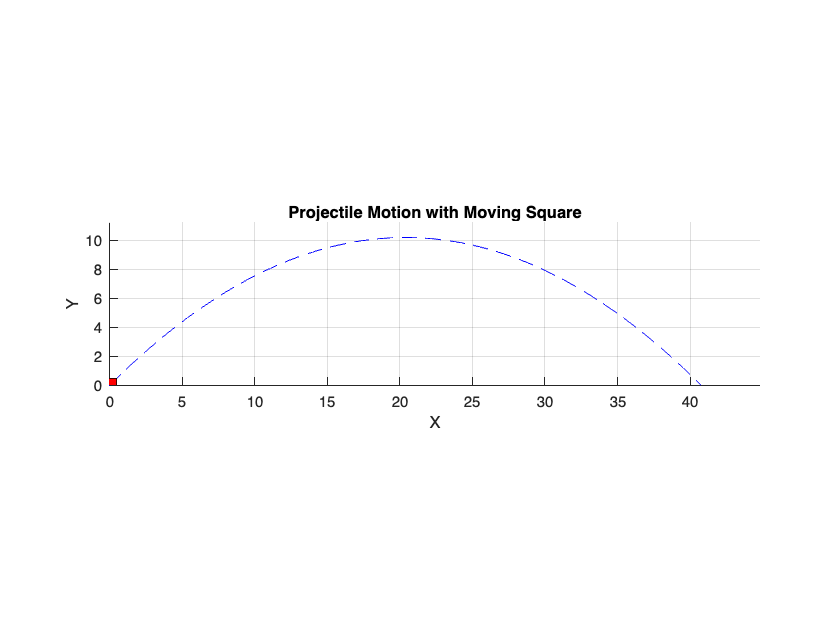

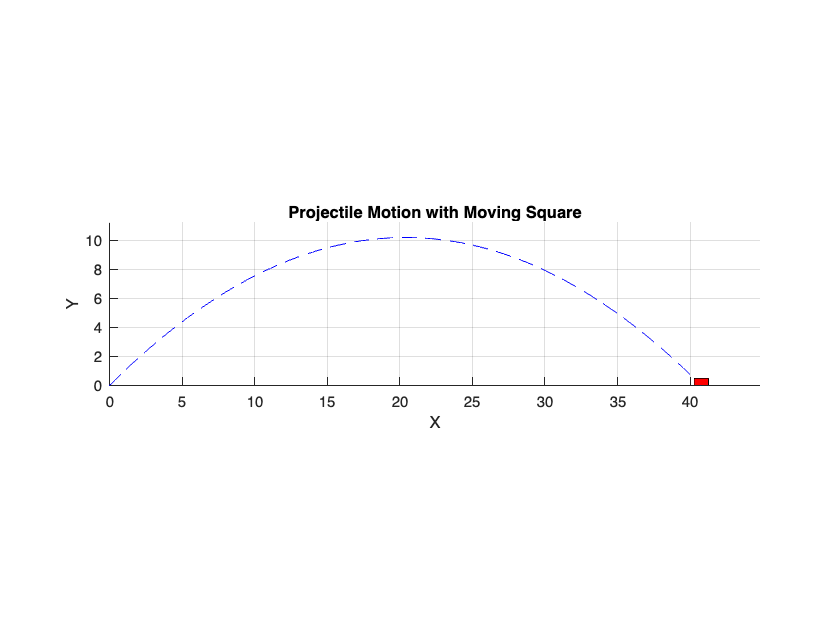

% Parameters
v0 = 20;                  % Initial velocity (m/s)
angle = 45;               % Launch angle (degrees)
g = 9.81;                 % Acceleration due to gravity (m/s^2)
t_total = 2 * v0 * sind(angle) / g;  % Time of flight

% Time vector
t = linspace(0, t_total, 100);

% Projectile path
x = v0 * cosd(angle) * t;
y = v0 * sind(angle) * t - 0.5 * g * t.^2;

% Square size
square_size = 1;

% Plot setup
figure;
axis equal;
axis([0 max(x)*1.1 0 max(y)*1.1]);
hold on;
grid on;
xlabel('X');
ylabel('Y');
title('Projectile Motion with Moving Square');

% Animation
for i = 1:length(t)
    % Clear previous square
    cla;

    % Plot full projectile path
    plot(x, y, 'b--');

    % Current position
    cx = x(i);
    cy = y(i);

    % Define square corners centered at (cx, cy)
    half_s = square_size / 2;
    square_x = [cx - half_s, cx + half_s, cx + half_s, cx - half_s, cx - half_s];
    square_y = [cy - half_s, cy - half_s, cy + half_s, cy + half_s, cy - half_s];

    % Plot the square
    fill(square_x, square_y, 'r');

    pause(0.05);
end